# 1070402 劉品彥 1070421 張舜程

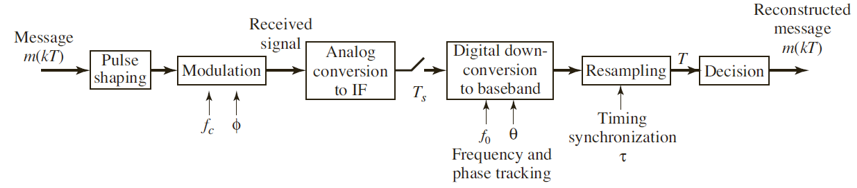

# Tx

## message

clear
close all
% APSK16.m: simulated 16-apsk transmission system
% TRANSMITTER
% change text to bit
mesLen = 4000

mesLen = 4000

bits=(sign(rand(1,mesLen)-.5)+1)/2;
j=sqrt(-1);
% offset setting
% Downsampler Timing Offset 
time_offset=0

time_offset = 0

phase_offset=1

phase_offset = 1

freq_offset=0

freq_offset = 0

symbol_period_offset=0

symbol_period_offset = 0

channel_noise_gain=0

channel_noise_gain = 0

channel_multipath=0

channel_multipath = 0

% ps time offset
toffset=20

toffset = 20

## Encode

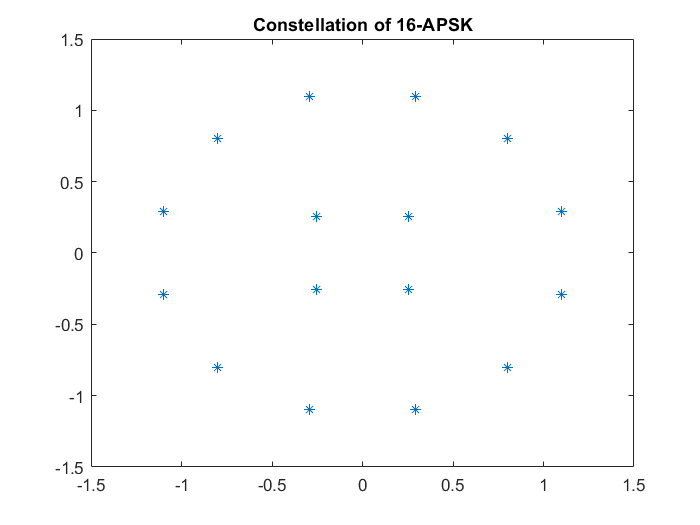

% 16-apsk signal
mapping_point=[4 12]; % 每一圈點的數量
gamma=3.15;
% r1=sqrt(16/(4+12*pow(gamma)));
r1=sqrt(16/(12*3.15^2+4));
r2=r1*gamma;
R=[r1 r2];
phi0=[pi/4 pi/12];
bitMapping=[12,14,15,13,4,0,8,10,2,6,7,3,11,9,1,5];         % 對應4bits的十進位
constellation=[];
for k=1:length(R)
    for kk=0:mapping_point(k)-1
        constellation=[constellation R(k)*exp(j*(2*pi*kk/mapping_point(k)+phi0(k)))];
    end
end
figure, plot(constellation,'*'), title("Constellation of 16-APSK")

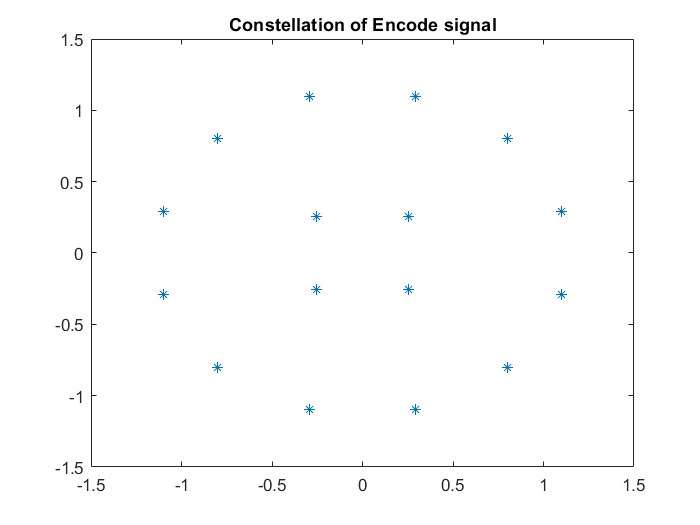

% Converting bits into decimal values for mapping 
matx = reshape(bits,4,length(bits)/4)'; 
mapp = bi2de(fliplr(matx),2)';  
symb= zeros(1,length(mapp)); 
% Mappinf the values onto the correspondant constellation points 
for i=1:length(mapp)
    [idx2,idx]= find(bitMapping == mapp(i)); 
    symb(i)= constellation(idx); 
end 
% The stream of 16apsk constellation symbols 
m=symb;
figure, plot(m,'*'), title("Constellation of Encode signal")

## Up sampling and Pulse shaping

N=length(m)

N = 1000

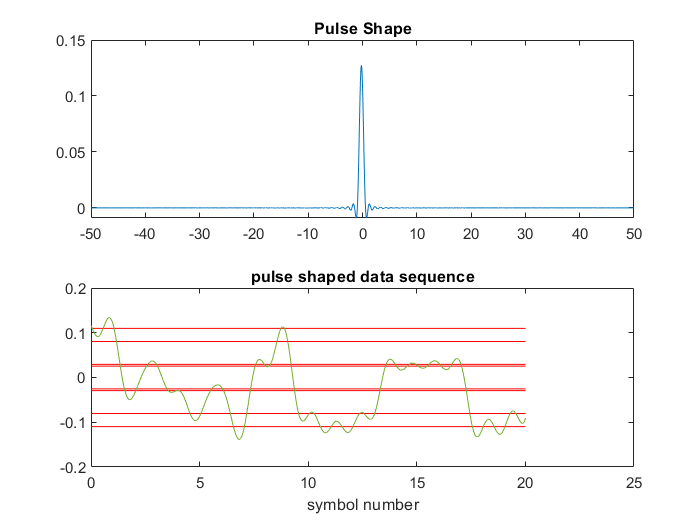

% zero pad T-spaced symbol sequence to create upsampled
% T/M-spaced sequence of scaled T-spaced pulses (T=1)
% Nyquist sampling freq(fs) > 2*(fc+BW)=2(20+4)=48
M=100-symbol_period_offset;                                 % oversmpling factor
% up sample
m_I=real(m);
m_Q=imag(m);
mup_I=zeros(1,N*M);
mup_I(1:M:end)=m_I;
mup_Q=zeros(1,N*M);
mup_Q(1:M:end)=m_Q;
figure, plotspec(mup_I,1/M), title("Signal before pulse shaping in I-phase")
% build pulse of width using srrc
beta=1;                                                     % rolloff parameter for srrc
L=50;                                                       % 1/2 the length of srrc pulse in symbol durations
ps=srrc(L,beta,M,toffset);
s_I=filter(ps,1,mup_I);                                     % symb in In-phase
s_Q=filter(ps,1,mup_Q);                                     % symb in Quadrature-phase
% 用In-phase確認是否有正確取樣
s_ps=s_I(L*M+1:20*M+L*M+1);                                 %look at the first 20 symbols
tps=[-L:1/M:L];                                             % time of ps
t_ps=1/M:1/M:(length(s_ps))/M;                              % time of the first 20 symbols
sc=sum(ps)/M;                                               % normalizing constant
plot_matrix=zeros(16,length(t_ps));                         % figure out if sample successful
for i=1:length(real(constellation))
    plot_matrix(i,:)=sc*real(constellation(i))*ones(size(s_ps));
end
figure,
subplot(2,1,1), plot(tps,ps), title("Pulse Shape")
subplot(2,1,2), plot(t_ps,plot_matrix,'r')
hold on
plot(t_ps,-plot_matrix,'r')
plot(t_ps,s_ps), title('pulse shaped data sequence')
xlabel('symbol number')
hold off

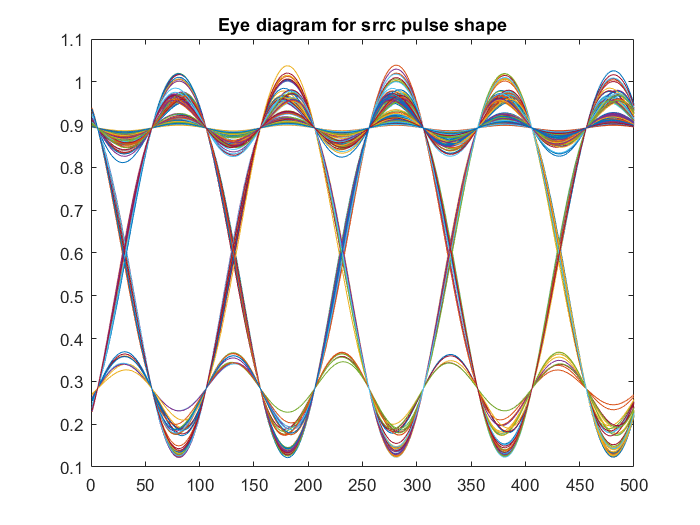

% 使用In-phase看eye patern
neye=5;
num_eye_plot=floor(length(s_I)/(neye*M));                   % number of eyes to plot
% plot eye patern of In-phase signal
% 使用眼圖檢查相位是否正確
m_amp=sqrt(m_I.^2+m_Q.^2);
mup_amp=zeros(1,N*M);
mup_amp(1:M:N*M)=m_amp;
ps_normalize=ps/max(ps);
s_normalize=filter(ps_normalize,1,mup_amp);
xp=s_normalize(N*M-neye*M*(num_eye_plot-3)+1:N*M);          % ignore transients at start
figure, plot(reshape(xp(35*M+1:end),neye*M,num_eye_plot-10)), title('Eye diagram for srrc pulse shape')

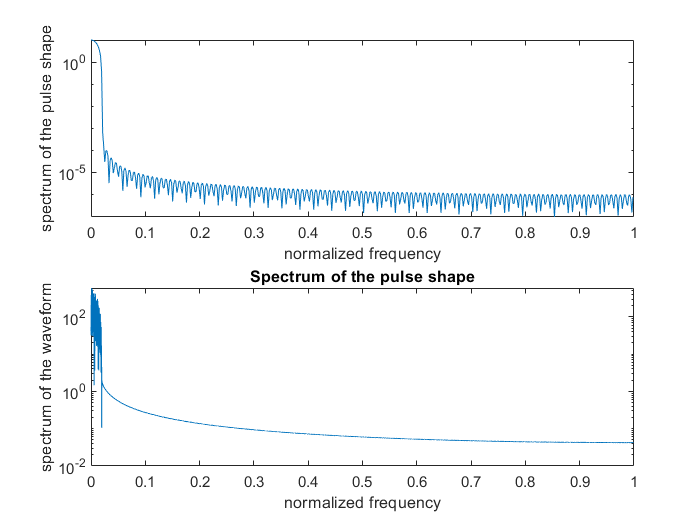

% Spectrum of the pulse shape
[h,w]=freqz(ps);
figure
subplot(2,1,1), semilogy(w/pi,abs(h))
ylabel('spectrum of the pulse shape')
xlabel('normalized frequency')
fftx=abs(fft(s_I));
subplot(2,1,2), semilogy(2*(1:length(fftx)/2)/length(fftx),fftx(1:length(fftx)/2))
title('Spectrum of the pulse shape')
ylabel('spectrum of the waveform')
xlabel('normalized frequency')

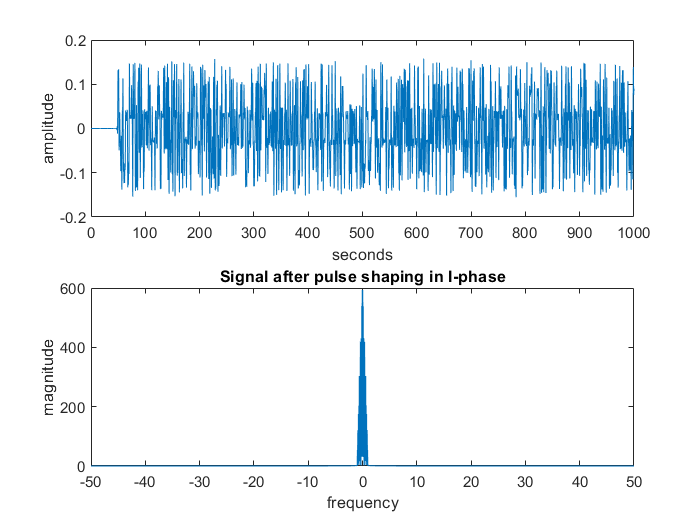

figure, plotspec(s_I,1/M), title("Signal after pulse shaping in I-phase")

## Transmit

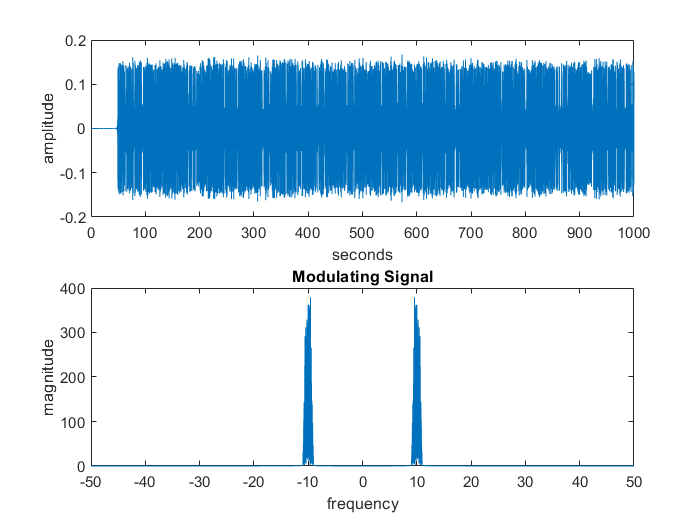

Ts=.0001;
time=Ts*(N*M-1);
t=0:Ts:time;
fc=1000;
v=s_I.*cos(2*pi*(fc+freq_offset)*t+phase_offset)-s_Q.*sin(2*pi*(fc+freq_offset)*t+phase_offset);
figure, plotspec(v,1/M), title("Modulating Signal")

# Channel

## Multipath Interference

%---------Multipath Interference-------------%
if channel_multipath < 0.5      % channel ISI
    mc=[1 0 0];                 % distortion-free channel

else                            % harsh multipath channel
    mc=[0.5 1 -0.6];
end
mc

mc =      1     0     0


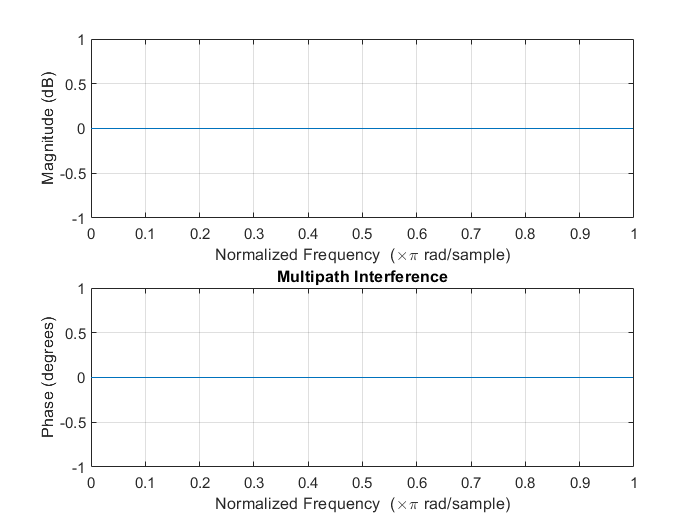

dv=filter(mc,1,v);              % filter signal through channel
figure, freqz(mc), title('Multipath Interference')

%---------Multipath Interference-------------%

## Time offset

dv=[zeros(1,time_offset) dv(1:end-time_offset)];

## AWGN

%-----------------AWGN-----------------------%
nvv=dv+channel_noise_gain*(randn(size(dv)));  % add Gaussian channel noise
%-----------------AWGN-----------------------%

## Time varying fading channel

%-----time-varying fading channel + AGC------%
ds=sum(sqrt(real(nvv).^2+imag(nvv).^2))/length(nvv)

ds = 0.0555

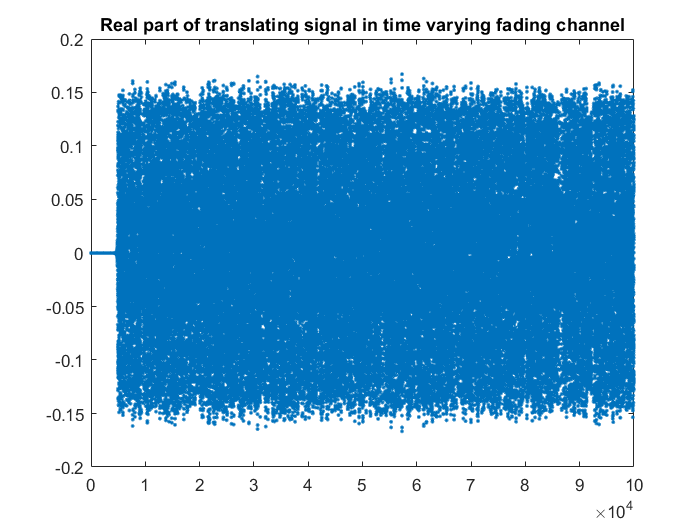

% time-varying fading channel
lr=length(nvv);
% fp=[ones(1,floor(0.2*lr)) 0.5*ones(1,lr-floor(0.2*lr))];
% nvv=nvv.*fp;
figure, plot([1:length(nvv)],real(nvv),'.'), title('Real part of translating signal in time varying fading channel')

nv=nvv;

## Symbol period offset

% add symbol period offset
Mr=M+symbol_period_offset;

## AGC

% % AGC
% g=zeros(1,lr); g(1)=1;
% nr=zeros(1,lr);
% mu_agc=0.01;
% for i=1:lr-1
%     nr(i)=g(i)*nvv(i);
%     g(i+1)=g(i)-mu_agc*(nr(i)^2-ds);
% end
% nv=nr/3;
% figure, plot([1:length(nv)],nv,'.')
% figure,
% subplot(3,1,2), plot(g)                 % plot AGC values
% title('Adaptive gain parameter')
% subplot(3,1,1), plot(real(nvv))        % plot inputs and outputs
% title('Input r(k)')
% subplot(3,1,3),plot(real(nr))
% title('Output g(k)')
% xlabel('iterations')
% %-----time-varying fading channel + AGC------%

## 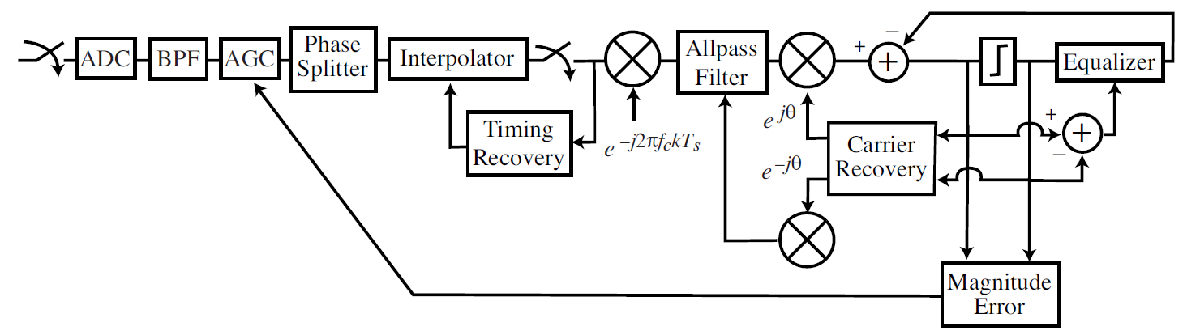

# Receiver

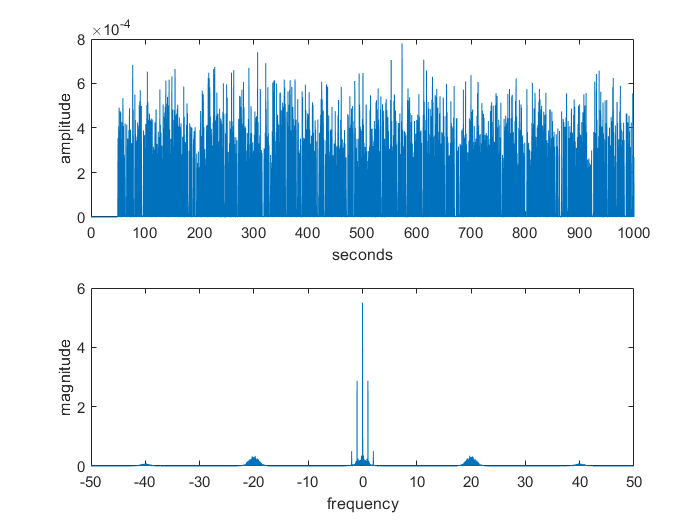

q=nv.^4;
fl=50; ff=[0 .38 .39 .41 .42 1];
fa=[0 0 1 1 0 0];                       % which is twice f_0
h=firpm(fl,ff,fa);                      % BPF design via firpm
rp=filter(h,1,q);                       % filter gives preprocessed r
figure,plotspec(q,1/M)

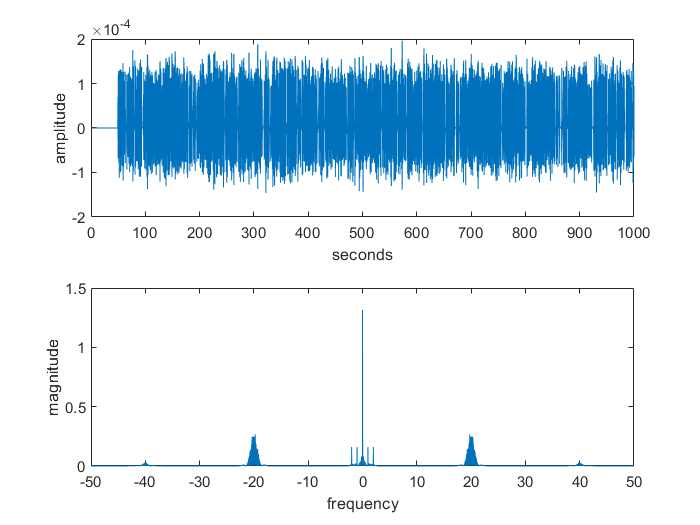

figure,plotspec(rp,1/M)

fl=50; ff=[0 .01 .02 1]; fa=[1 1 0 0];
h=firpm(fl,ff,fa);
mu=1000;                                % algorithm stepsize
f0=1000;                                % freq at receiver
theta=zeros(1,length(t)); theta(1)=0;   % initialize estimates
z=zeros(1,fl+1);                        % initialize LPF
for k=1:length(t)-1                     % z contains past inputs
  z=[z(2:fl+1), rp(k)*sin(8*pi*f0*t(k)+4*theta(k))];
%   update=fliplr(h)*z';                % new output of LPF
  update=filter(fliplr(h),1,z);
  theta(k+1)=theta(k)-mu*mean(update);  % algorithm update
end
theta(length(theta))

ans = 3.4899

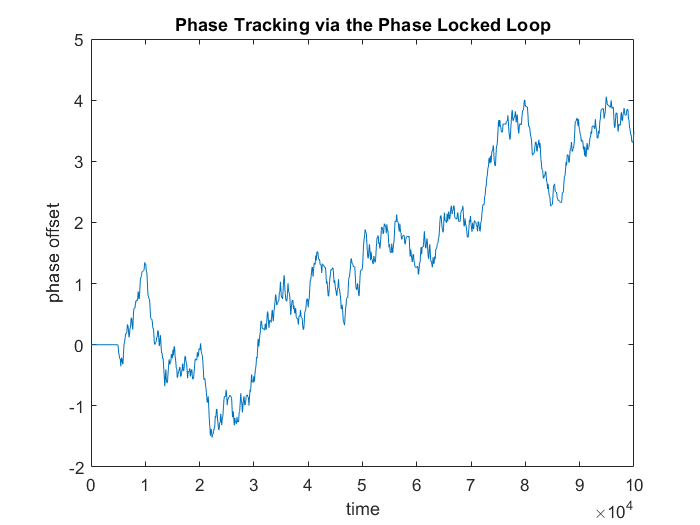

figure,plot(theta)
title('Phase Tracking via the Phase Locked Loop')
xlabel('time'); ylabel('phase offset')

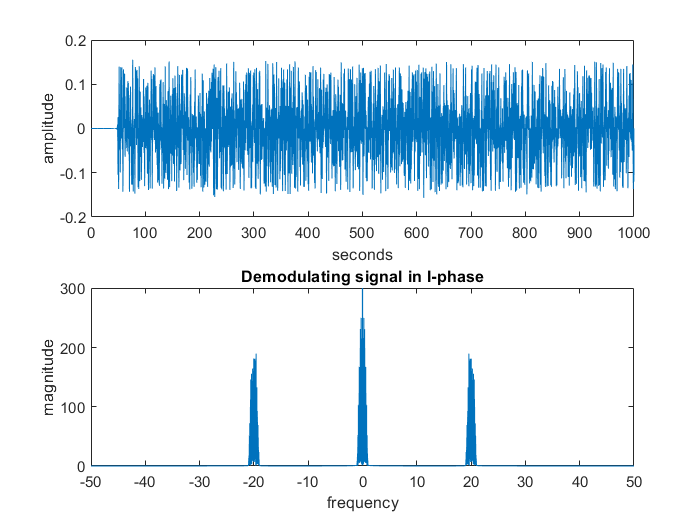

% add phase offset and frequency offset
x_I=nv.*cos(2*pi*(fc+freq_offset)*t+theta(length(theta)));
x_Q=nv.*sin(2*pi*(fc+freq_offset)*t+theta(length(theta)));
x_rec = x_I+j*x_Q;
figure, plotspec(x_I,1/Mr), title("Demodulating signal in I-phase")

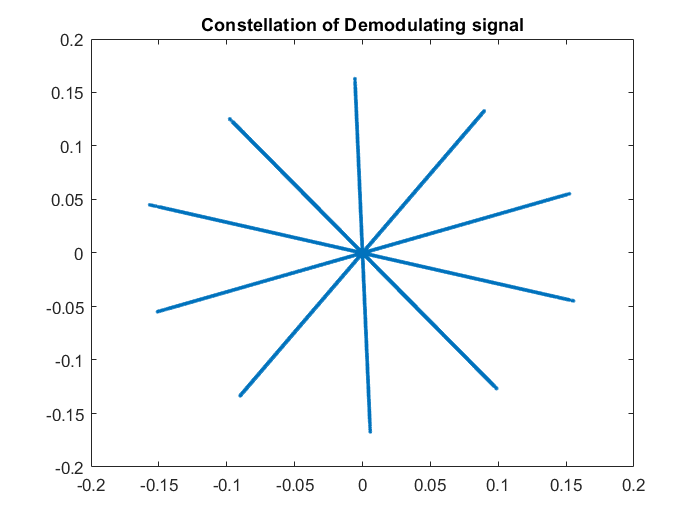

figure, plot(x_I,x_Q,'.'), title("Constellation of Demodulating signal")

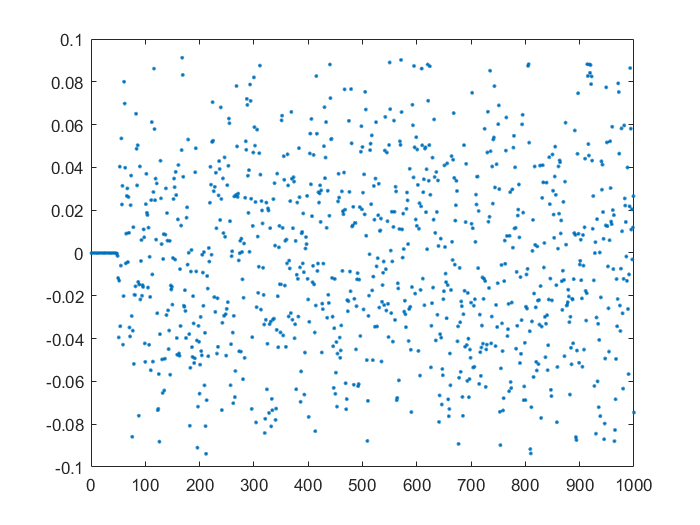

% debug
debug=x_I(1+(L/2):M:N*M);
figure, plot([1:length(debug)],debug,'.')

## A mixer with phase adaptation via Preprocessing and PLL

### LPF

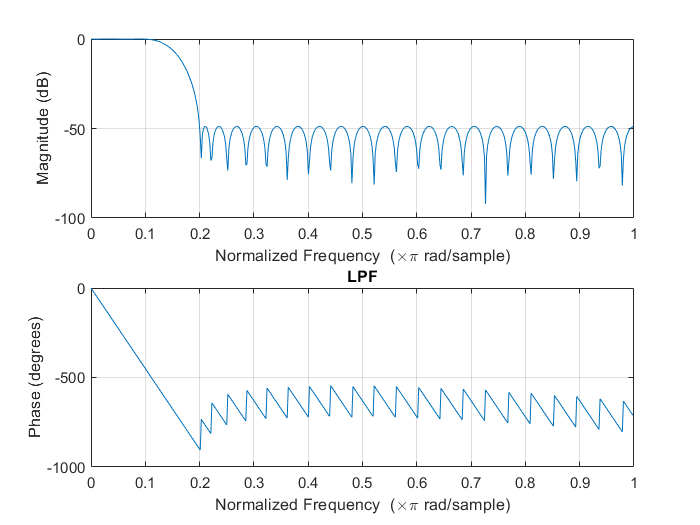

% LPF
fl=50;
fbe=[0 0.1 0.2 1];
damps=[1 1 0 0];
b=firpm(fl,fbe,damps);
figure, freqz(b), title('LPF')

### **Baseband Derotation**

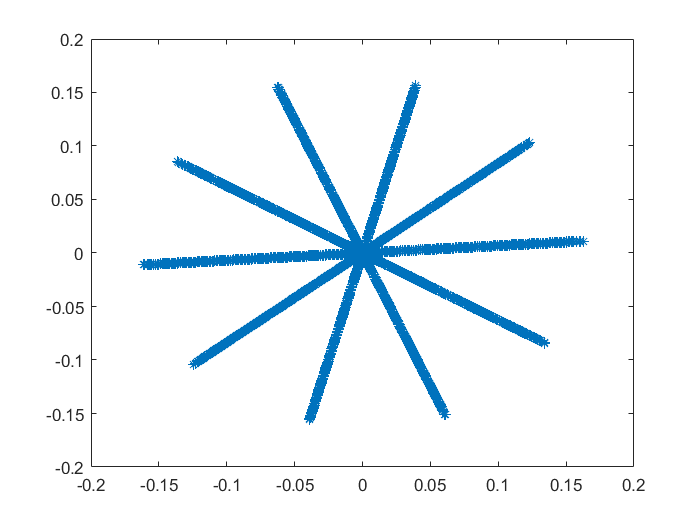

% derotate a complex-valued 16-APSK signal
q=x_rec.*exp(j*theta(length(theta)));
plot(real(q),imag(q),'*')

const_r=uniquetol(real(constellation));
const_i=uniquetol(imag(constellation));
mu=10000; theta1=zeros(1,N);                      % initialize variables
buf_IQ =[];
for i=1:N-1                                     % adapt through all data
  x=exp(j*theta1(i))*q(i);                      % x=rotated(r)
  x1=real(x); x2=imag(x);                       % real and imaginary parts
  shat1=quantalph(real(q(i)),const_r);          % hard decisions
  shat2=quantalph(imag(q(i)),const_i);
  theta1(i+1)=theta1(i)-mu*(shat1*x2-shat2*x1); % iteration
  
  buf_IQ = [buf_IQ x1+j*x2];
end
figure(1)
plot(real(q),imag(q),'*')

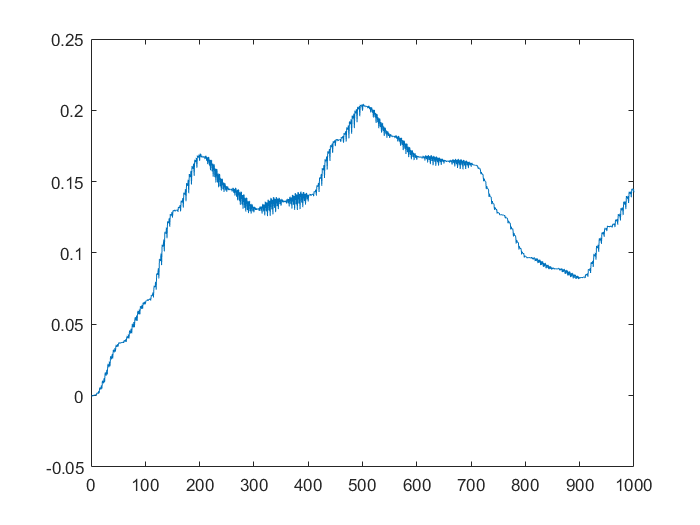

figure(2)
plot(theta1)

figure(3)
plot(real(buf_IQ(600:end)),imag(buf_IQ(600:end)),'*')
theta1(length(theta1))

ans = 0.1425

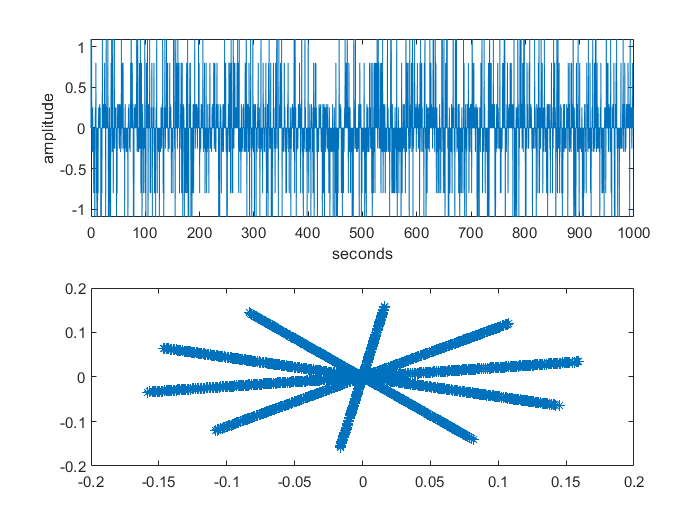

q_after_derot = q.*exp(j*theta1(length(theta1)));
plot(real(q_after_derot),imag(q_after_derot),'*')

x_I = real(q_after_derot);
x_Q = imag(q_after_derot);

% % 使用 Costas loop 解決 phase offset
% mu=0.01;
% q=fl+1;                    % freq at receiver
% for i=1:10
%     th1=zeros(1,length(t)); 
%     th1(1)=randn; % initialize estimate
%     th2=zeros(1,length(t)); 
%     th2(1)=randn;
%     th=zeros(1,length(t)); 
%     th(1)=0;
%     z11=zeros(1,q);
%     z12=zeros(1,q);       % initialize LPFs
%     z13=zeros(1,q);       % z's contain past inputs
%     z14=zeros(1,q); 
%     z21=zeros(1,q); 
%     z22=zeros(1,q);       % initialize LPFs
%     z23=zeros(1,q);
%     z24=zeros(1,q); 
%     for k=1:length(t)-1
%       s=2*v(k);
%       z11=[z11(2:q),s*cos(2*pi*fc*t(k)+th1(k))];
%       z12=[z12(2:q),s*cos(2*pi*fc*t(k)+pi/4+th1(k))];
%       z13=[z13(2:q),s*cos(2*pi*fc*t(k)+pi/2+th1(k))];
%       z14=[z14(2:q),s*cos(2*pi*fc*t(k)+3*pi/4+th1(k))];
%       lpf11=fliplr(b)*z11';               % output of filter 1
%       lpf12=fliplr(b)*z12';               % output of filter 2
%       lpf13=fliplr(b)*z13';               % output of filter 3
%       lpf14=fliplr(b)*z14';               % output of filter 4
%       th1(k+1)=th1(k)+mu*lpf11*lpf12*lpf13*lpf14; % algorithm update
%       z21=[z21(2:q),s*cos(2*pi*fc*t(k)+th(k))];
%       z22=[z22(2:q),s*cos(2*pi*fc*t(k)+pi/4+th(k))];
%       z23=[z23(2:q),s*cos(2*pi*fc*t(k)+pi/2+th(k))];
%       z24=[z24(2:q),s*cos(2*pi*fc*t(k)+3*pi/4+th(k))];
%       lpf21=fliplr(b)*z21';               % output of filter 1
%       lpf22=fliplr(b)*z22';               % output of filter 2
%       lpf23=fliplr(b)*z23';               % output of filter 3
%       lpf24=fliplr(b)*z24';               % output of filter 4
%       th2(k+1)=th2(k)+mu*lpf21*lpf22*lpf23*lpf24; % algorithm update
%       th(k+1)=th1(k)+th2(k);
%     end
%     plot(t,th),hold on
% end
%     
% 
% % plot(t,th1),
% % title('th1 Phase Tracking via the Costas Loop')
% % xlabel('time'); ylabel('phase offset')
% % plot(t,th2),
% % title('th2 Phase Tracking via the Costas Loop')
% % xlabel('time'); ylabel('phase offset')
% % plot(t,th),
% title('th Phase Tracking via the Costas Loop')
% xlabel('time'); ylabel('phase offset')

% c_recovery=cos(2*pi*fc*t+theta(length(t)));

% c_recovery=cos(2*pi*fc*t);
% Demodulator
% x_recovery=r.*c_recovery;
% figure, plotspec(x_recovery,1/Up_sample)

## Lowpass filtering for downconversion, matched filter, and interpolation all provided by a matched filter with adjusted timing offset adapted with maximization of the fourth power of downsampled signals in dual-loop configuration

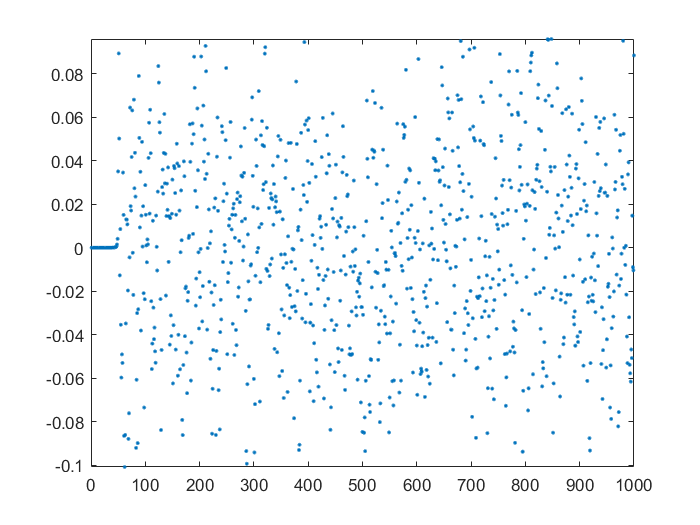

% lowpass filtering for downconversion
x_I_lpf=2*filter(b,1,x_I);
x_Q_lpf=2*filter(b,1,x_Q);
x_Q_lpf=-x_Q_lpf;

% debug
debug=x_I_lpf(1+L/2+fl/2:M:N*M);           
figure, plot([1:length(debug)],debug,'.') 

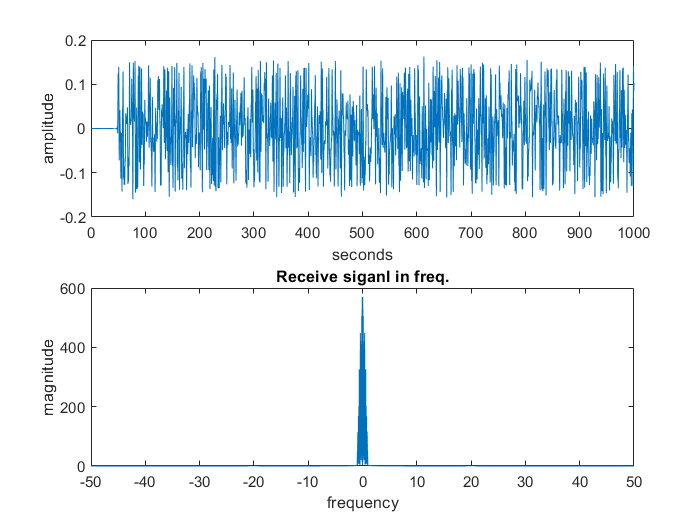

figure, plotspec(x_I_lpf,1/Mr), title("Receive siganl in freq.")

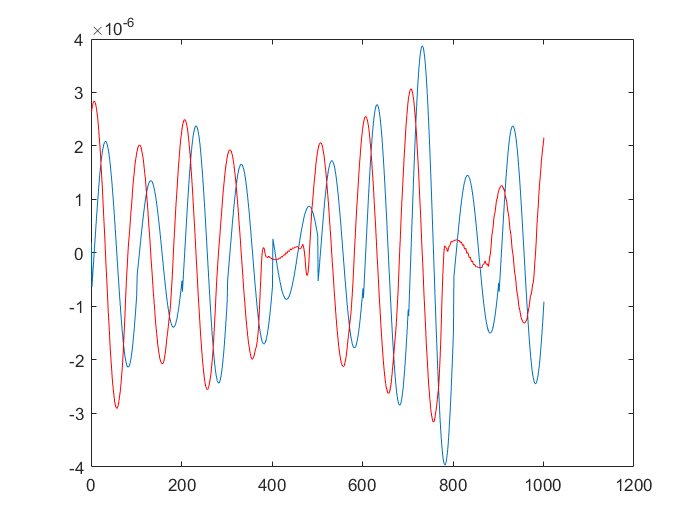


% debug
figure,plot(s_Q(500:1500))              % compare transmitted and received
hold on
plot(x_Q_lpf(500+L:1500+L),'r')         % imaginary parts
hold off

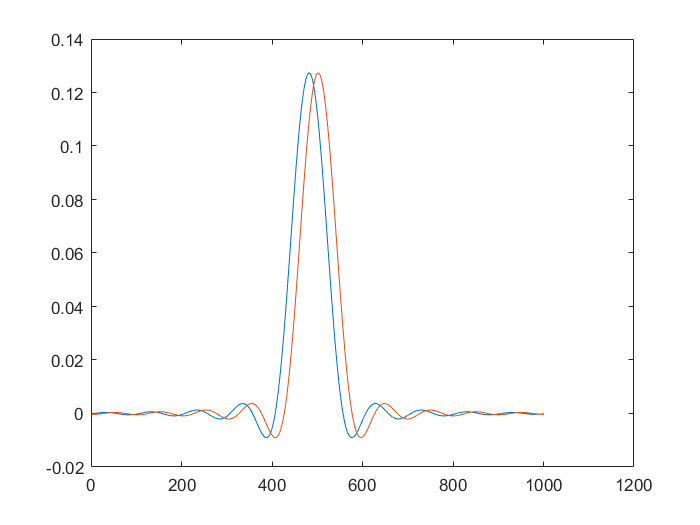

matchfilt=srrc(L,beta,Mr,0);
plot_lenght_ps_timeoffset=(length(matchfilt)-1)*45/100 : (length(matchfilt)-1)*55/100;
figure, plot([ps(plot_lenght_ps_timeoffset).' matchfilt(plot_lenght_ps_timeoffset).'])

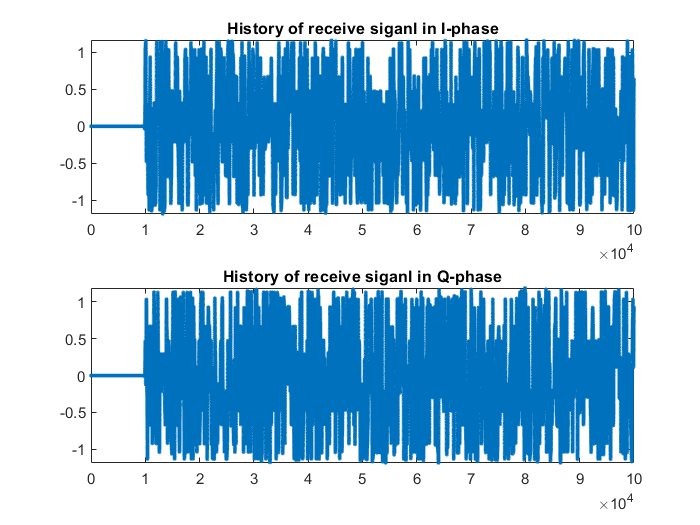

x_I_match=filter(fliplr(matchfilt),1,x_I_lpf);
x_Q_match=filter(fliplr(matchfilt),1,x_Q_lpf);
subplot(2,1,1), plot([1:length(x_I_match)],x_I_match,'.'), title("History of receive siganl in I-phase")
subplot(2,1,2), plot([1:length(x_Q_match)],x_Q_match,'.'), title("History of receive siganl in Q-phase")

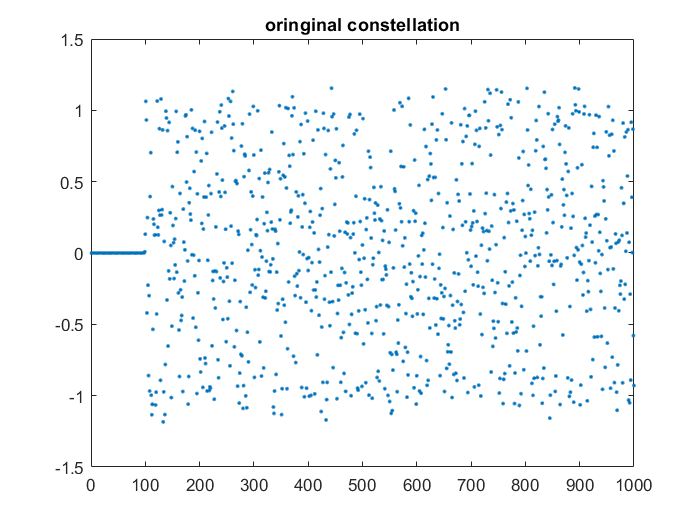


% debug
debug=x_I_match(1+(L/2):M:N*M);
figure, plot([1:length(debug)],debug,'.'),title('oringinal constellation')

### Time Recovery

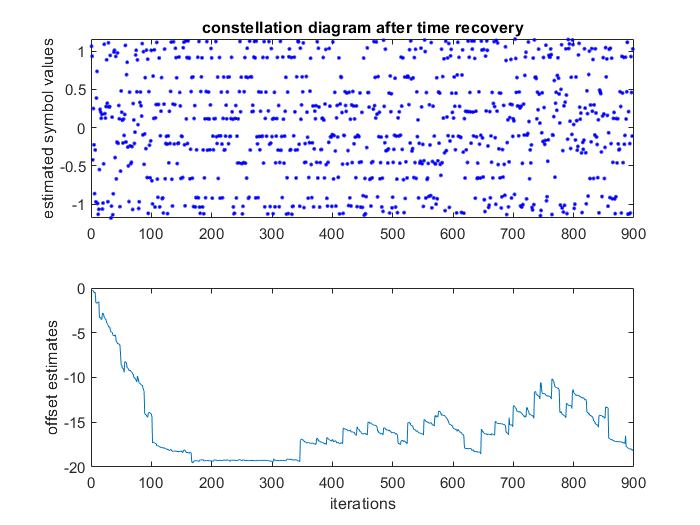

tnow=2*Mr*L+L/2+1;                                  % initialize variables
tau=0;
ms_I=zeros(1,N);
ms_Q=zeros(1,N);
tausave=zeros(1,N); tausave(1)=tau; i=0;
mu=200;                                             % algorithm stepsize
delta=0.1;                                          % time for derivative
while tnow<length(x_I_match)+L/2                    % run iteration
  i=i+1;
  ms_I(i)=interpsinc(x_I_match,tnow+tau,L);         % interp at tnow+tau
  ms_Q(i)=interpsinc(x_Q_match,tnow+tau,L);
  m_deltap_I=interpsinc(x_I_match,tnow+tau+delta,L);    % value to right
  m_deltap_Q=interpsinc(x_Q_match,tnow+tau+delta,L);
  m_deltam_I=interpsinc(x_I_match,tnow+tau-delta,L);    % value to left
  m_deltam_Q=interpsinc(x_Q_match,tnow+tau-delta,L);
  
  dm_I=m_deltap_I-m_deltam_I;                       % numerical derivative
  dm_Q=m_deltap_Q-m_deltam_Q;
  
  ms_taup_I=interpsinc(x_I_match,tnow+tau,L);
  ms_taup_Q=interpsinc(x_Q_match,tnow+tau,L);
  
  tau=tau+mu*((ms_taup_I^3)+(ms_taup_Q^3))*(dm_I+dm_Q);    % alg update (energy)
  tnow=tnow+Mr; tausave(i)=tau;      % save for plotting
end
figure, subplot(2,1,1), plot(ms_I(1:i-2),'b.')      % plot constellation diagram
title('constellation diagram after time recovery');
ylabel('estimated symbol values')
subplot(2,1,2), plot(tausave(1:i-2))                % plot trajectory of tau
ylabel('offset estimates'), xlabel('iterations')

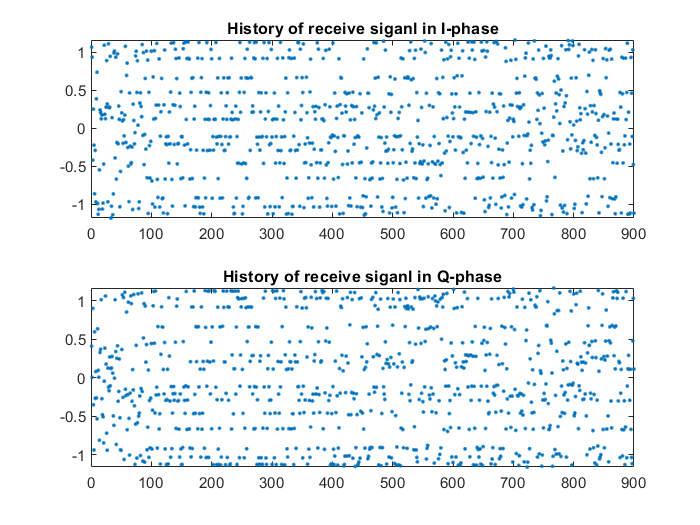


% correlator
z_I=ms_I(1:length(ms_I)-2*L);
z_Q=ms_Q(1:length(ms_Q)-2*L);
z_complex=z_I+j*z_Q;
figure, 
subplot(2,1,1), plot(z_I,'.'), title("History of receive siganl in I-phase")
subplot(2,1,2), plot(z_Q,'.'), title("History of receive siganl in Q-phase")

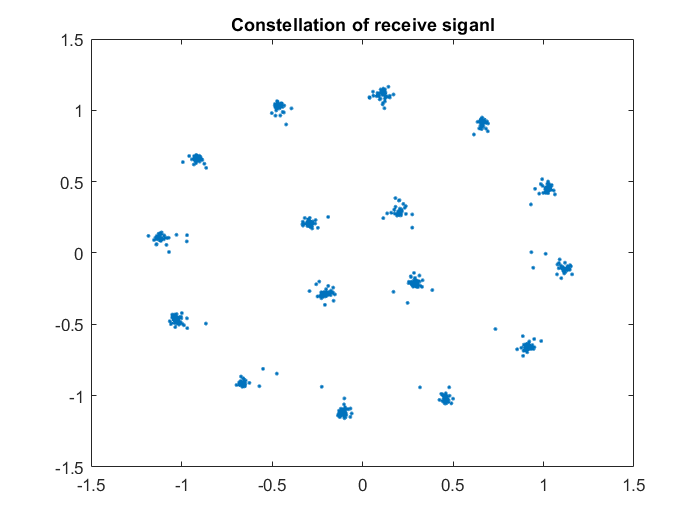

figure, plot(z_complex,'.'), title("Constellation of receive siganl")

% debug
zero_count=0;
for i=1:length(z_I)
    if ((abs(z_I(i))+abs(z_Q(i)))<0.2)
        zero_count=zero_count+1;
    else
        continue
    end
end
zero_count

zero_count = 0

## Linear equalizer adaptation via LMS; switched to decision-directed LMSadaptation during the data (i.e. non-training) portion

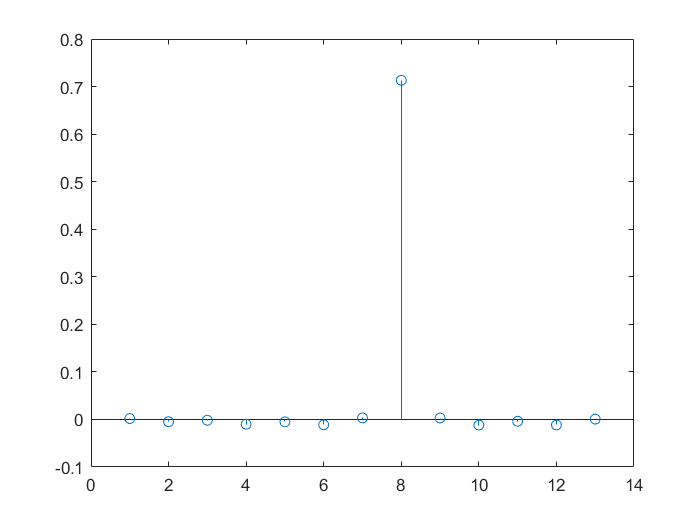

% % decision device and symbol matching performance assessment
n_LMS=13;
f_LMS=zeros(n_LMS,1);
mu_LMS=0.003;
delta_LMS=7;
y_LMS=zeros(n_LMS,1);
buf=[];
for i=n_LMS+1:length(z_I)
    rr=z_I(i:-1:i-n_LMS+1);
    y_LMS(i)=rr*f_LMS;
    e=z_I(i-delta_LMS)-y_LMS(i);
    f_LMS=f_LMS+mu_LMS*e*rr';
    buf=[buf f_LMS];
end
figure(),stem(real(f_LMS))

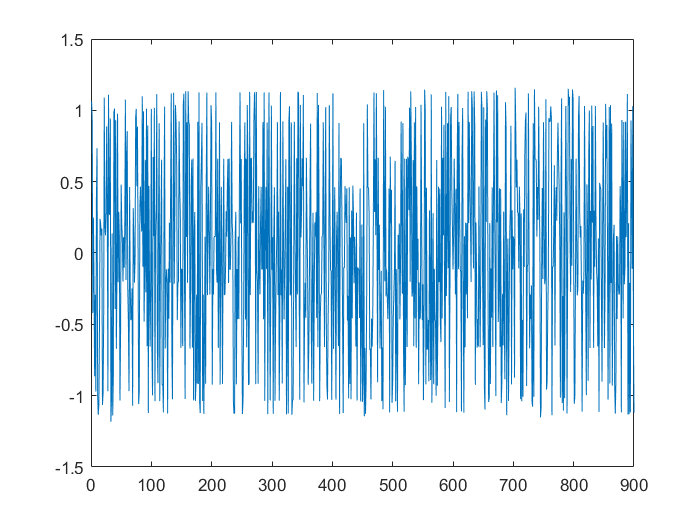

figure(),plot(z_I)

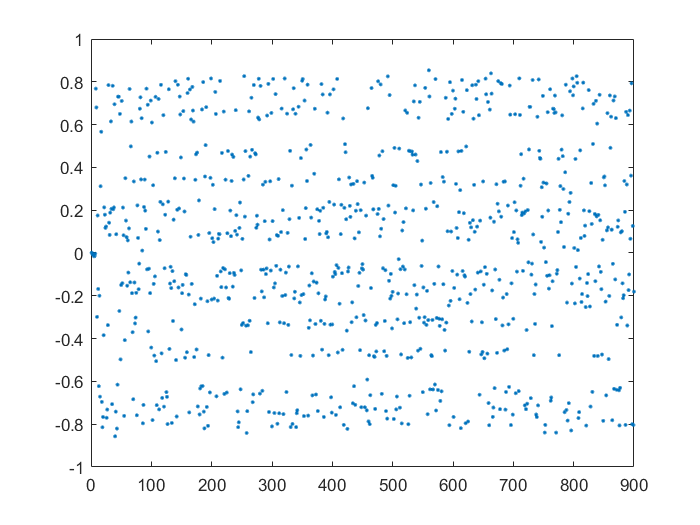

y_LMS=filter(f_LMS,1,z_I);
figure(),plot(y_LMS,'.')

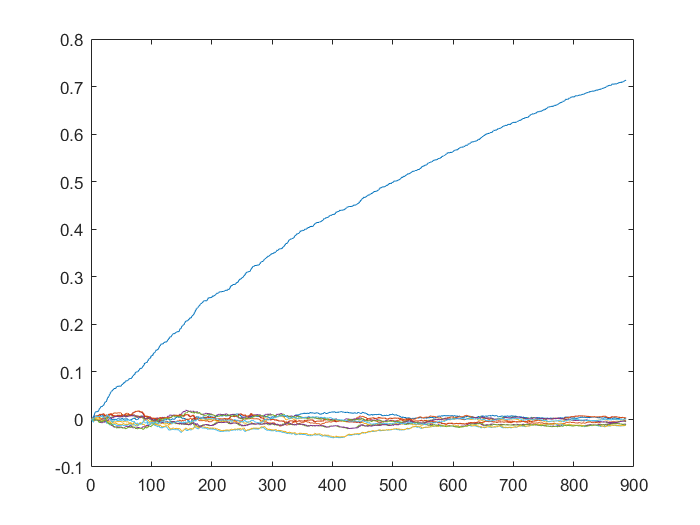

figure(),plot(real(buf.'))

y_LMS_Q=filter(f_LMS,1,z_Q);
% Quantize
quan_z=zeros(1,length(z_I));
for i=1:length(z_I)
    min_num=min( abs(real(constellation)-z_I(i)) + abs(imag(constellation)-z_Q(i)) );
    dist_real=abs(real(constellation)-z_I(i));
    dist_imag=abs(imag(constellation)-z_Q(i));
    [~,index]=find(((dist_real+dist_imag)-min_num)<1e-3,1);
    quan_z(i)=constellation(index);
end
len_quan_z=length(quan_z);

%debug
dif_symb=0;
dif_col=[];
for i=1:len_quan_z
    if ((abs(real(quan_z(i))-real(symb(i)))+abs(imag(quan_z(i))-imag(symb(i))))>1e-4)
        dif_symb=dif_symb+1;
        dif_col=[dif_col i];
    else
        continue
    end
end
dif_symb % different symbols in total

dif_symb = 2

dif_col

dif_col =      2    37


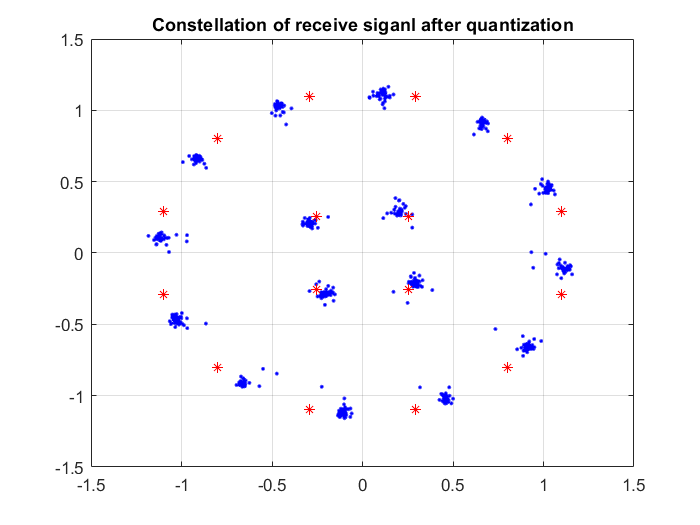

figure, plot(z_complex,'b.'), title("Constellation of receive siganl")
hold on
plot(quan_z,'r*'), title("Constellation of receive siganl after quantization")
grid

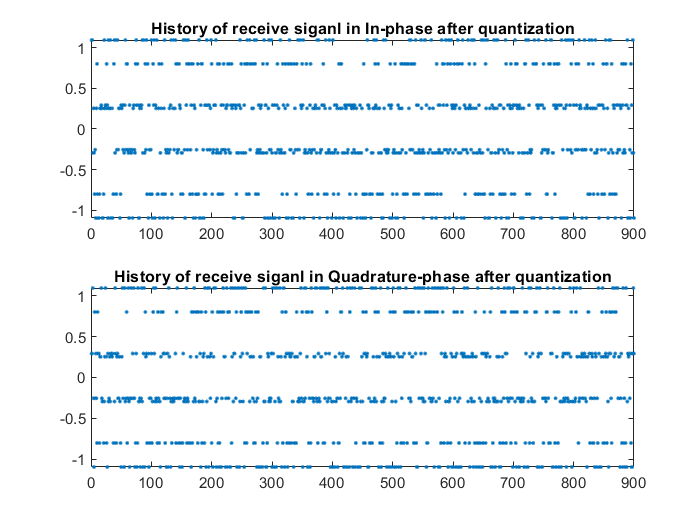

figure, 
subplot(2,1,1), plot([1:length(quan_z)],real(quan_z),'.'), title("History of receive siganl in In-phase after quantization")
subplot(2,1,2), plot([1:length(quan_z)],imag(quan_z),'.'), title("History of receive siganl in Quadrature-phase after quantization")

% cluster variance
cluster_variance=(quan_z-z_complex(1:length(quan_z)))*(quan_z-z_complex(1:length(quan_z)))'/length(quan_z)

cluster_variance = 0.0276

## Decode

% decoder
demap = zeros(length(quan_z),4); 
for i=1:length(quan_z)
    index=find((abs(real(constellation)-real(quan_z(i))) + abs(imag(constellation)-imag(quan_z(i))) )==0);
    demap(i,:)=fliplr((de2bi(bitMapping(index),4))); 
end
% The final 16apsk demmaped bit stream 
y_dem=reshape(demap',1,length(quan_z)*4);
% The final 16apsk demmaped bit stream 
L_y_dem=length(y_dem);

% debug
different_bits=0;
for i=1:L_y_dem
    if(abs(y_dem(i)-bits(i))==1)
        different_bits=different_bits+1;
    else
        continue
    end
end
different_bits % different bits in total

different_bits = 2

pererr=100*sum(abs(sign(y_dem-bits(1:L_y_dem))))/L_y_dem % symbol error

pererr = 0.0556

Symbol error rate for 16-APSK in AWGN channel

N0=10.^(0:-.2:-10);                % noise variances
s=symb;
const=uniquetol(real(constellation));            % normalized symbol values
allsers = zeros(size(N0));
for i=1:length(N0)                % loop over SNR
  n=sqrt(N0(i)/2)*(randn(1,N)+j*randn(1,N));
  r=s+n;                          % received signal+noise
  realerr=quantalph(real(r),const)==quantalph(real(s),const);
  imagerr=quantalph(imag(r),const)==quantalph(imag(s),const);
  SER=1-mean(realerr.*imagerr);   % determine SER by counting
  allsers(i)=SER;                 % # symbols w/ RE+IM correct
end
pow(s)

ans = 1.0035

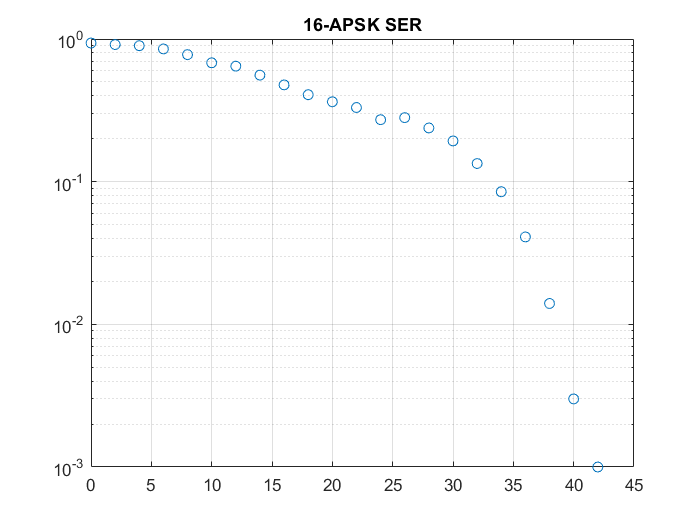

figure, semilogy(10*log10(1./N0),allsers,'o'),title('16-APSK SER')
grid